ii)Then, write code in Matlab to solve your problem from (i) to determine the solution u(x). Compare your result to that from (a) at the grid nodes. 

h=0.25 and $h=\frac{1}{n+1}$

so$n=\frac{1}{h}-1=3$

From the resulte above $K=\left\lbrack \begin{array}{ccc}
-2 & 1 & 0\\
1 & -2 & 1\\
0 & 1 & -1
\end{array}\right\rbrack$

From equation (1)


$$\begin{array}{l}
\left\lbrack U_{i+1} -2U_i +U_{i-1} \right\rbrack =h^2 f\left(x\right)\\
\left\lbrack U_{i+1} -2U_i +U_{i-1} \right\rbrack =h^2 \left(x_i -2\right)
\end{array}$$


To build K

From the resulte above $K=\left\lbrack \begin{array}{ccc}
-2 & 1 & 0\\
1 & -2 & 1\\
0 & 1 & -1
\end{array}\right\rbrack$

if we use

n=3;
e = ones(n, 1);
K1 = spdiags([-e, 2*e, -e], -1:1, n, n)

K1 =    (1,1)        2
   (2,1)       -1
   (1,2)       -1
   (2,2)        2
   (3,2)       -1
   (2,3)       -1
   (3,3)        2


We could findout that the sign is opposite with the function we want

So

e = ones(n, 1);
K2 = -spdiags([-e, 2*e, -e], -1:1, n, n)

K2 =    (1,1)       -2
   (2,1)        1
   (1,2)        1
   (2,2)       -2
   (3,2)        1
   (2,3)        1
   (3,3)       -2


And also, for i=n, from the problem


$$u^{\prime } \left(1\right)=4$$



$$\begin{array}{l}
\frac{U_{n+1} -U_n }{h}=4\\
U_{n+1} -U_n =4h\\
U_{n+1} =4h+U_n 
\end{array}$$


so the last term of the equation (1) is 

$\begin{array}{l}
\left\lbrack 4h+U_n -2U_n +U_{n-1} \right\rbrack =h^2 \left(x_i -2\right)\\
\left\lbrack -U_n +U_{n-1} \right\rbrack =h^2 \left(x_i -2\right)-4h
\end{array}$            (2)

So the last term of K is -1.

And for vector b, according to equation (1)

$b_i =h^2 \left(x_i -2\right)$                                            (3)

Also from (2), the last term of b is:

$b_n =h^2 \left(x_n -2\right)-4h$                                    (4)

clear
h = 0.25;%define h
n = 1/h-1; %compute n
u0 = 0;%boundary condition u(0)=0

x = linspace(1/(n + 1), 1 - 1/(n + 1), n);%define xi

x =     0.2500    0.5000    0.7500


r = realf(x); %calculate the ture value
u = finap(n, u0) %calculate the approximation value

u =     1.2812
    2.4531
    3.5312


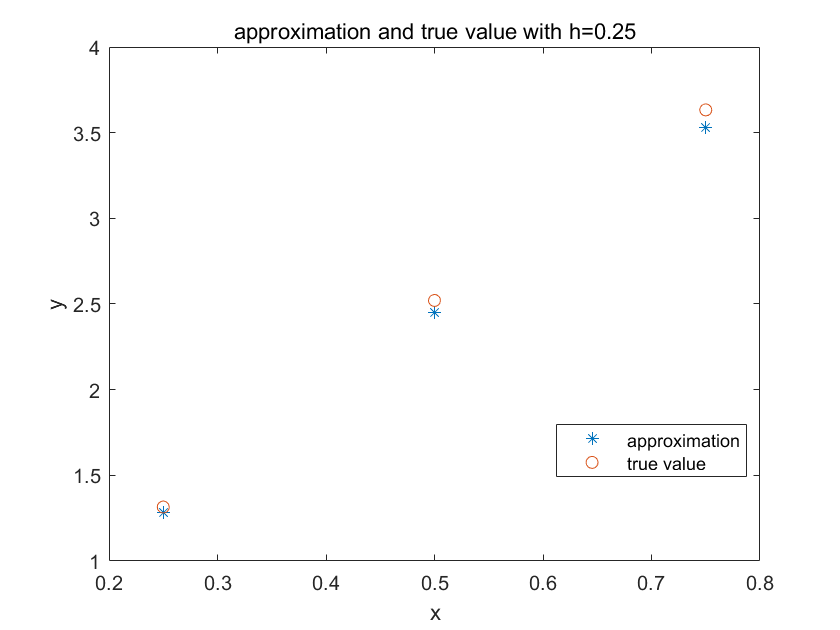


%plot the value
plot(x, u, '*')
hold on
plot(x, r, 'o')
xlabel('x')
ylabel('y')
title('approximation and true value with h=0.25')
legend('approximation','true value','Location','best')
hold off

The approximate value is a little bit off the true value

error_h_0_25=sum(abs(u(:)-r(:)))

error_h_0_25 = 0.2031

The total error of n=3 is 0.2031

(iii) Generalize your code to solve the problem with $h=\frac{1}{20}$ .

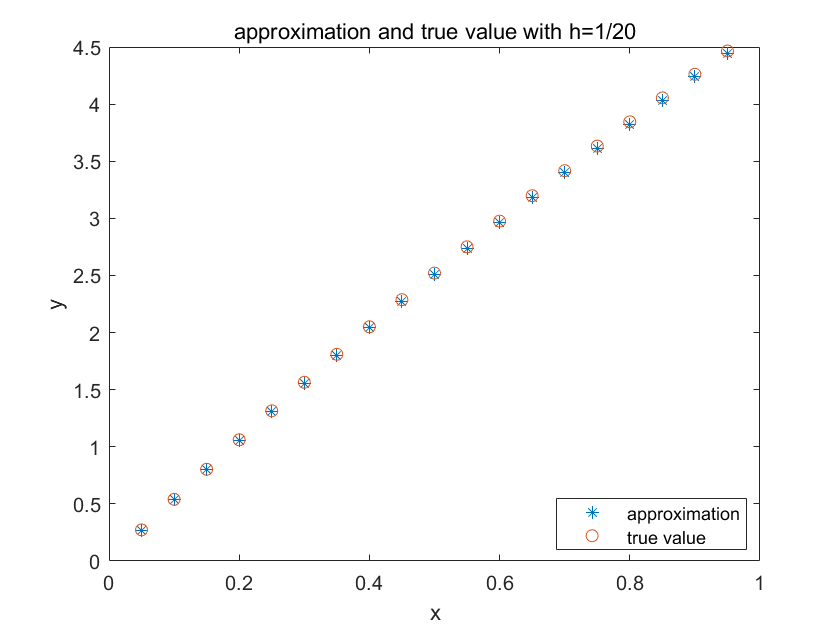

clear
h2 = 1/20;%define h
n2 = 1/h2-1; %compute n
u0 = 0;%boundary condition u(0)=0

x2 = linspace(1/(n2 + 1), 1 - 1/(n2 + 1), n2);%define xi
r2 = realf(x2); %calculate the ture value
u2 = finap(n2, u0); %calculate the approximation value

%plot the value
plot(x2, u2, '*')
hold on
plot(x2, r2, 'o')
xlabel('x')
ylabel('y')
title('approximation and true value with h=1/20')
legend('approximation','true value','Location','best')
hold off

From the plot we could find out that, at the begining of the plot, the approximate value are almost the same as the true value, but with x increasing the error become larger.

error_h_0_005=sum(abs(u2(:)-r2(:)))

error_h_0_005 = 0.2415

The total error of h=1/20 is 0.2415

function [y] = f(xi)
%Function of compute f(x) from du^2/d^2x=f(x)
    y = xi-2;
end

function [r]=realf(x)
%Function of compute the true value for comparison. from (a)
    r = 1/6*x.^3 - x.^2+11/2*x;
end

function [u] = finap(n, u0)
%Function of finite difference approximation
    h = 1/(n + 1); %compute h
    xi = linspace(0, 1, n + 2); %define xi
    xi = xi(2:n + 1); %only need x1 to xn
    b = f(xi)*h*h; %equation (3)
    b(end) = b(end) - 4*h; %equation (4)
    e = ones(n, 1);
    K = -spdiags([-e, 2*e, -e], -1:1, n, n);%form Kn matrix of n by n 
    K(n, n) = -1;%modify Kn by changing the (n,n) element to 1
    u = K\b';%calculating

end

